## ECOLOGICAL MODELLING

# ASSIGNMENT 1

This project is aimed at providing any reader with short hands-on experience in ecological modelling. Ecological modelling is the construction and analysis of mathematical models of ecological processes, including both purely biological and combined biophysical models. Models can be analytic or simulation-based and are used to understand complex ecological processes and predict how real ecosystems might change.

I studied different growth models of 5 tree species. For the reference, please see the original MW Project 5 pdf. The project contains two assignments and the final work. 

To begin with, we initialize some characteristics of tree species: max diameters, max heights, species names and model parameters b2,b3:

close all; clc; format short;
Dmax = [153,122,50,50,46];
Hmax = [3011,2660,1830,1830,1830];
species = ["maple","beech","fir","spruce","birch"];
b2 = zeros(1,5); b3 = zeros(1,5);

warning('off','all')

A continuous model of tree hight $H(t)$ as a function of a tree diameter $D(t)$ is given as $H(D)= 137 + b2*D-b3*D^2$, with two conditions $H(Dmax)=Hmax$ and $$ \frac{dH}{dD}(Dmax)=0 $$. By incorporating conditions into a model, we can solve for b2 and b3 parameters in terms of Hmax and Dmax. Intuitively, first condition states that whenever a maximum diameter is reached, it also reaches a max height, while the second condition says that any tree won't be growing further from that point. We can graph the growth of 5 trees.

for i = 1:5
b2(i) = 2* (Hmax(i) - 137) / Dmax(i);
b3(i) = (Hmax(i) - 137) / Dmax(i)^2;
i = i+1;
end

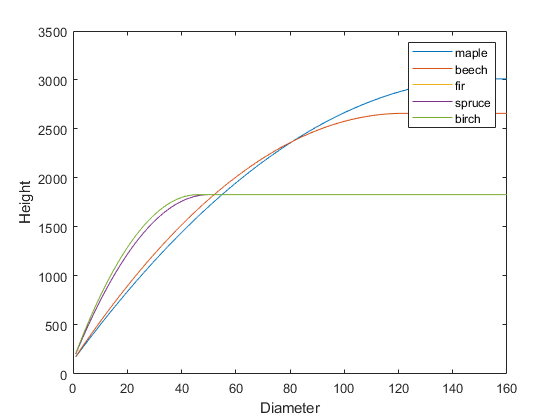

for i= 1:5
    for D = 1:160 
        if D < Dmax(i)
            Height(D) = 137 + b2(i)*D - b3(i)*D.^2;
        elseif D > Dmax(i) - 1
            Height(D) = Hmax(i);
        end
        D = D+1;
    end
D = 1:160;    
plot(D,Height);
drawnow
pause(1)
xlabel('Diameter');
ylabel('Height');
legend("maple","beech","fir","spruce","birch");
hold on

end

Next, our aim is to study the tree diameter growth rate. We use functions of tree height $H(D(t))$ and tree leaf area $LA(t)$ to extract from the bole volume growth function $V(t)$ the growth rate of tree diameter function $D(t)$, namely a term $\frac{dD}{dt}
$. Precisely, given $V(D)=HD^2$ and $\frac{dV}{dt} =LA(D(t))*(1-\frac{H*D}{Hmax*Dmax})$,where $LA(D(t))=GD^2$, by applying the Chain Rule as $\frac{dV}{dt}=\frac{dV(D)}{dD}*\frac{dD}{dt}$, we can extract the $\frac{dD}{dt}$ as the equation below (line 35).

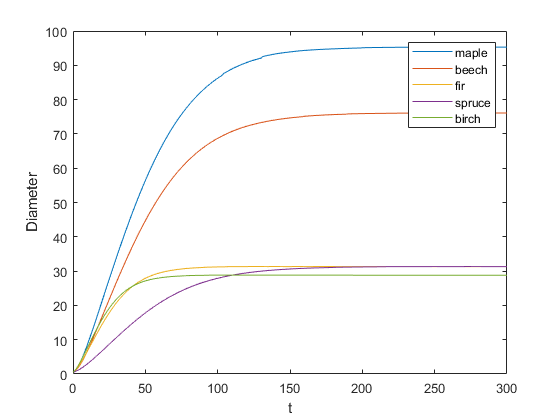

for k = 1:5
    figure(2)
    G=[170,150,200,100,240]; % G is a parameter
    dD = @(t,D) G(k)*D^2*(Hmax(k)*Dmax(k)-137*D-b2(k)*D^2-b3(k)*D^3)/(3*b2(k)*D^2*Hmax(k)*Dmax(k)+274*D*Hmax(k)*Dmax(k));
    D0 = 0.5;
    T = 300;
    G=[170,150,200,100,240];
    [t, DD] = ode113(dD, 0:T, D0,[]);
    plot(t,DD);
    pause(1)
    xlabel('t');
    ylabel('Diameter');
    legend("maple","beech","fir","spruce","birch");
    hold on
    
end

As a result we indeed reach maximum heights as expected for every tree specie we have. Next, we transform our model to a discrete form and validate that it gives reasonable results as well. Indeed, if we change an increment from 2 steps to 1 step at a time, we will get results almost identical to the previous continuous curves. Oppositely, the wider a time step is, the less accurate numerical estimates are. Try with timestep=1,5,10. 

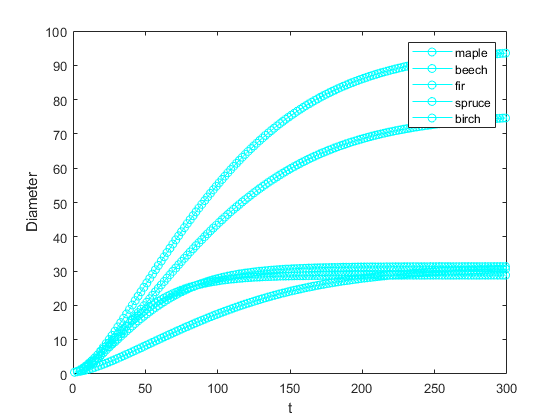

for k = 1:5
    timestep = 2; 
    dD_t = @(D) D + G(k)*D^2*(Hmax(k)*Dmax(k)-137*D-b2(k)*D^2-b3(k)*D^3)/(3*b2(k)*D^2*Hmax(k)*Dmax(k)+274*D*Hmax(k)*Dmax(k));
    tt = 1:timestep:T;
    DD = zeros(length(tt),1);
    DD(1) = D0;
    for z = 1:length(tt)-1
        DD(z+1) = dD_t(DD(z));
    end
    
    figure(3)
    plot(tt, DD,'co-');
    pause(1)
    xlabel('t');
    ylabel('Diameter');
    legend("maple","beech","fir","spruce","birch");
    hold on;
    
end

# ASSIGNMENT 2

In this assignment we are going to simulate the growth of 1000 individual trees, which can either survive or die out at the end of every year. We will utilize a discrete growth model to simulate the growth and death of trees, and analyze how long trees live. Maximum ages for tree species, as well as a dying probability variable $\epsilon$ are defined in the code. At the maximum age, AGEmax, statistically only $2\%$ of the trees are still alive. It implies that every year the probability to survive is $1 - \epsilon$. After N years, it will be $(1-\epsilon)^N$. At the AGEmax we are basically solving the following equation for its positive roots within [0,1] interval.

age_max=[200,300,80,350,80];

syms epsilon
assume(epsilon,'positive')
assume(epsilon>0 & epsilon<1)
species=["maple","beech","fir","spruce","birch"];
solx=[0,0,0,0,0];
%R = zeros(5,2)

for i=1:5
    eqn =(1-epsilon)^age_max(i) == 0.02;
    solx(i)= solve(eqn,epsilon);
    R(i,:) = [species(i),solx(i)];
end
    
R % species and respective survival probability at AgeMax

R = 5×2 string array
    "maple"     "0.01937" 
    "beech"     "0.012955"
    "fir"       "0.047724"
    "spruce"    "0.011115"
    "birch"     "0.047724"

We will sumulate 1000 trees of one kind only, for the sake of saving some computational time. The same junk of code can be run for other species as well (by changing the tree index). We expect to get the statistical survival rate, which has to be 98% for at most AgeMax years, as we stated before. We will also draw a histogram of the tree diameters at their maximum age. 

A few remarks: 

- every year whether a tree lives or dies is decided by a random value in between [0,1] interval. You might notice that probabilites we've got above are in [0, 0.05] percentage interval. Obviously the generated random value will be higher than 0.05 therefore we will have a simulation that represents the process of tree growth in desirable environment, under all conditions necessary for survival. If we would like to simulate the environment where trees lack nutritions, sunlight, space, shadow, and other vital condition, we can modify our random number generator to produce results the frequently appear under 0.05.

- We are about to simulate 1000 maple trees.

- We will show the histogram ages and number of trees. 

G=[170,150,200,100,240];
dD_t = @(D) D + G(1)*D^2*(Hmax(1)*Dmax(1)-137*D-b2(1)*D^2-b3(1)*D^3)/(3*b2(1)*D^2*Hmax(1)*Dmax(1)+274*D*Hmax(1)*Dmax(1));
p_die = solx(1)

p_die = 0.0194

T = 1000;
tt = 0:1:T;
nsim = 1000;
DD = zeros(length(tt),nsim);
D0 = 0.5;
DD(1,:) = D0; % the same initial diameter for each simulated tree

ages = zeros(1,nsim);
for i = 1:nsim
 for t = tt(2:end) 
  ages(i) = ages(i) + 1;
  r = rand();
  % r = 0.1*rand(); 
  if r < p_die
   break;
  else
   DD(t+1,i) = dD_t(DD(t,i));
  end
 end
end

p = 0.98; 
ageP = quantile(ages, p)  % here we see that indeed only 2% of survived trees reach the age close to 200

ageP = 192

sum(ages > ageP)/nsim % expected to be very close to 0.02 = 2%

ans = 0.0200

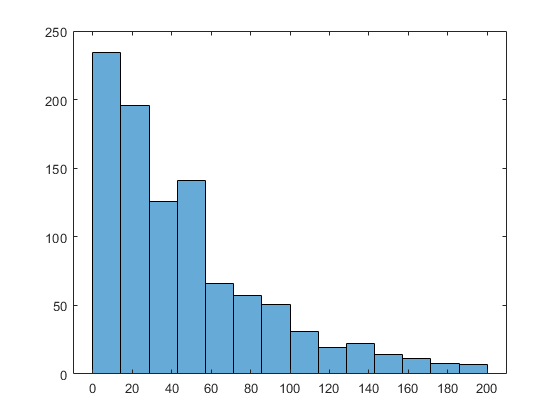

figure(4); clf;
histogram(ages,'BinLimits',[0,200])

# FINAL ASSIGNMENT 

In this section we will address an interesting question: how five tree species would grow while competing against each other for natural resources?  The math is heavy, but it is important to understand it before proceeding with the code. The interaction between two tree species is modelled through 


$$x_i(t+1)= x_i(t) + a_i*x_i,t*(1 - x_i(t)/K_i) *r(AL)$$
 

for $0 < x_i < K_i
$ , $x_1,x_2,x_3,x_4,x_5$ = diameters of five individual species, r(AL) = rate limiting factor, depending on the amount of available light AL (defined below).

To model natural resources, such as the amount of shadow and sunlight available for every tree, we define:

- the leaf area of canopy as $A_i = c_i*x_i^2$ 

- If the tree j is higher than tree l, $H_j > H_l
$, there is less available light for tree l, and the light available for tree l is measured as $AL_l = e^\frac{-SLA_l}{1.2}$, where $SLA_l = \sum_{k} A_k $ for all k such that $H_l > H_k$ ( = 0 otherwise). SLA stands for the shadowing leaf area. Obviously for the highest tree, the shadowing leaf area is zero. 

- Species can also be tolearant and intolerant for the shadow. We define type 1 as tolerant for the shadow, and type 2 as intolerant.$r_1(AL_1) = 1.0098 *(1 - e^{-4.640*AL_1})
$,    $r_2(AL_2) = 1.4730 *(1 - e^{-1.136*AL_2}).$

Now we can move to the assignment itself. Assume that we own a forest with five possible tree species. Tolerance types are defined as 1 and 2 in a vector. I created a model that includes the components needed to monitor how five species succeed in the competition for light and space. Notice the growth process here differs from the very first plot at the beginning of this live script, where tree species were not competing and grew independly.  

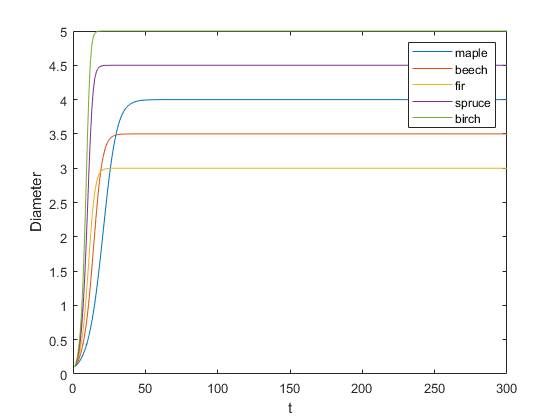

T = 300; 
tt = 1:T;

% parameters are given
a1=0.2; a2=0.3; a3=0.4; a4=0.5; a5=0.6;
K1=4; K2=3.5; K3=3; K4=4.5; K5=5;
c1=0.2; c2=0.25; c3=0.15; c4=0.3; c5=0.4;
h1=10; h2=8; h3=11; h4=9; h5=7;

R_ALTOL = @(AL) 1.0098*(1-exp(-4.64*AL)); %shadow tolerant (type 1) 
R_ALINTOL = @(AL) 1.4730*(1-exp(-1.136*AL)); %shadow intolerant (type 2)

species=["maple","beech","fir","spruce","birch"];
tree_tolerance_types = [2,2,1,2,1]; % tolerance types

% preallocate memories
D = zeros(T,5);
D(1,:) = 0.1; 

AL = zeros(T,5);

SLA = zeros(T,5);

A= zeros(T,5);

dD_t = zeros(T,5);

H1 =  h1*D(:,1)/K1;
H2 =  h2*D(:,2)/K2;
H3 =  h3*D(:,3)/K3;
H4 = h4*D(:,4)/K4;
H5 = h5*D(:,5)/K5;
H = [H1,H2,H3,H4,H5];

for z = 1:T-1
     
     A(z,1) = c1*D(z,1); 
     A(z,2) = c2*D(z,2); 
     A(z,3) = c3*D(z,3); 
     A(z,4) = c4*D(z,4);
     A(z,5) = c5*D(z,5);
     
     
     for i = 1:5
         for j = 1:5
             if H(z,i) > H(z,j)
                 SLA(z,i) = SLA(z,i) + A(z,j);
             else
                continue;
             end
         end
     end

     AL(z,:) = exp(SLA(z,:)/1500);    
   
     dD_t(z,1) =  D(z,1) + a1*D(z,1)*(1-D(z,1) /K1)*R_ALINTOL(AL(z,1));     
     dD_t(z,2) =  D(z,2) + a2*D(z,2)*(1-D(z,2)/K2)*R_ALINTOL(AL(z,2));
     dD_t(z,3) =  D(z,3) + a3*D(z,3)*(1-D(z,3)/K3)*R_ALTOL(AL(z,3));
     dD_t(z,4) =  D(z,4) + a4*D(z,4)*(1-D(z,4)/K4)*R_ALINTOL(AL(z,4));   
     dD_t(z,5) =  D(z,5) + a5*D(z,5)*(1-D(z,5)/K5)*R_ALTOL(AL(z,5));
     
     D(z+1,:) = dD_t(z,:);
   
end
  
    
figure(5)
plot(tt, D(:,1));
xlabel('t');
ylabel('Diameter');
hold on;
plot(tt, D(:,2));
hold on;
plot(tt, D(:,3));
hold on;
plot(tt, D(:,4));
hold on;
plot(tt, D(:,5));
legend("maple","beech","fir","spruce","birch");